global A x0;
A = [2 -3; 6 -4];
B = [0; 0]; C = [1 0; 0 1]; D = [0; 0];

poles = [-1, -0.5];  % Zadane wartości własne
[num, den] = tfdata(zpk(0, poles, 1, 1));
eA = tf2ss(num{1}, den{1})

eA =    -1.5000   -0.5000
    1.0000         0



eigvals = eig(eA)   % Sprawdzenie

eigvals =    -1.0000
   -0.5000



A1 = eA;
A1k = jordan(eA)  % Postać kanoniczna

A1k =    -1.0000         0
         0   -0.5000


Węzeł asymptotycznie stabilny, e1 = -1, e2 = -0.5

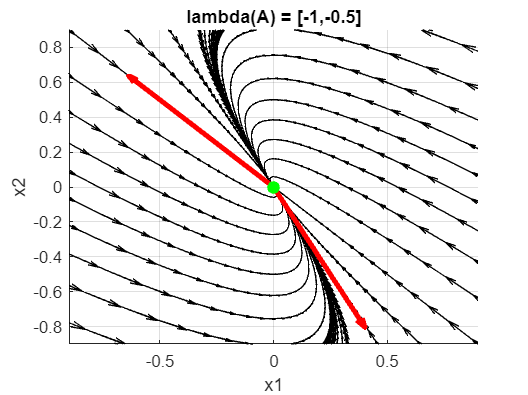

A = A1;
draw_phase()
axis([-0.9 0.9 -0.9 0.9]);

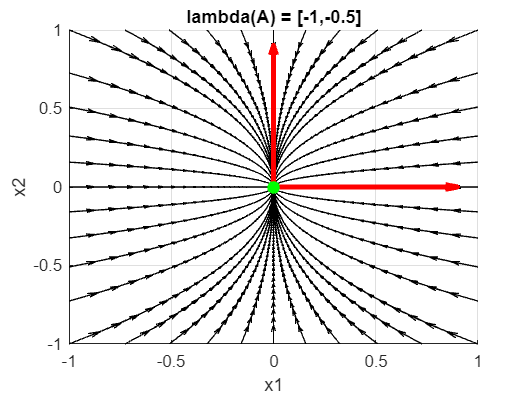

A = A1k;
draw_phase()
axis([-1 1 -1 1]);

Węzeł asymptotycznie niestabilny, e1 = 1, e2 = 0.5

poles = [1, 0.5];  % Zadane wartości własne
[num, den] = tfdata(zpk(0, poles, 8, 1));
eA = tf2ss(num{1}, den{1})

eA =     1.5000   -0.5000
    1.0000         0


eigvals = eig(eA)   % Sprawdzenie

eigvals =     1.0000
    0.5000



A1n = eA;
A1nk = jordan(eA)  % Postać kanoniczna

A1nk =     0.5000         0
         0    1.0000


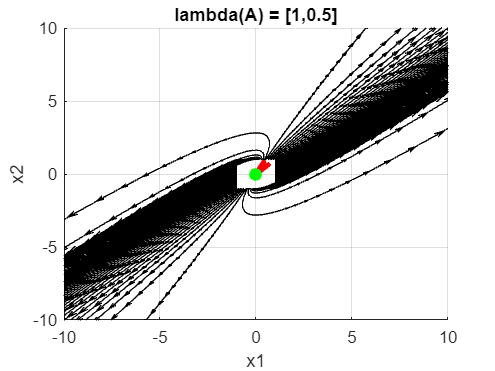


A = A1n;
draw_phase()
axis([-10 10 -10 10]);

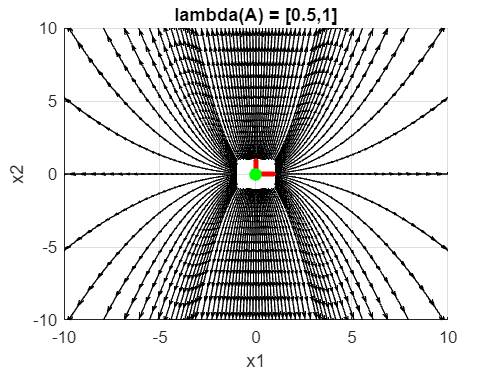

A = A1nk;
draw_phase()
axis([-10 10 -10 10]);

Siodło, e1 = -2, e2 = 1

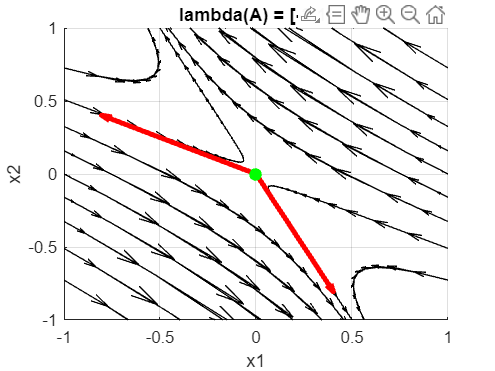

A2 = [-3 -2; 2 2];
A2k = [-2 0; 0 1]; 

A = A2;
draw_phase()
axis([-1 1 -1 1]);

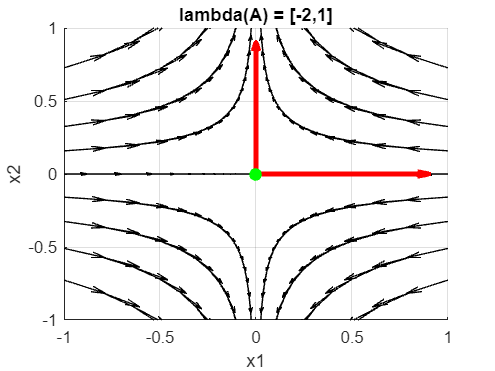

A = A2k;
draw_phase()
axis([-1 1 -1 1]);

Ognisko stabilne, e1 = -1 + 3j, e2 = -1 - 3j

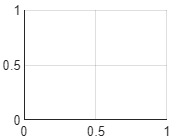

Error using lab1_portrety_fazowe>draw_phase
Invalid setting in 'model/State-Space' for parameter 'B'.

Caused by:
    Error using lab1_portrety_fazowe>draw_phase
    Error evaluating parameter 'B' in 'model/State-Space'
        Error using lab1_portrety_fazowe>draw_phase
        Unrecognized function or variable 'B'.
            Error using <a 

A3 = [2 -3; 6 -4];
A3k = [-1 3; -3 -1];

A = A3;
draw_phase()

axis([-0.8 0.8 -0.8 0.8]);
A = A3k;
draw_phase()
axis([-0.8 0.8 -0.8 0.8]);

Ognisko niestabilne, e1 = 1 + 3j, e2 = 1 - 3j

poles = [1 + 3j, 1 - 3j];  % Zadane wartości własne
[num, den] = tfdata(zpk(0, poles, 8, 1));
eA = tf2ss(num{1}, den{1})

eA =      2   -10
     1     0


eigvals = eig(eA)   % Sprawdzenie

eigvals =    1.0000 + 3.0000i
   1.0000 - 3.0000i



A3n = eA;
A3nk = jordan(eA)  % Postać kanoniczna

A3nk =    1.0000 - 3.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   1.0000 + 3.0000i



A = A3n;
draw_phase()

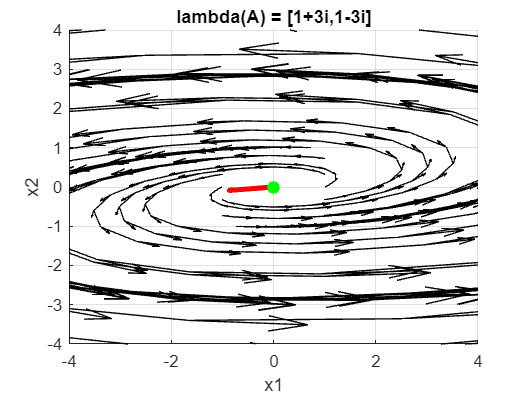

axis([-4 4 -4 4]);

A = A3nk

A =    1.0000 - 3.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   1.0000 + 3.0000i


% draw_phase()
% axis([-3 3 -3 3]);

Środek, e1 = -3j, e2 = 3j

A4 = [-1 2; -5 1];
A4k = [0 3; -3 0]

A4k =      0     3
    -3     0



A = A4;
draw_phase()

w =    0.1690 - 0.5071i   0.1690 + 0.5071i
   0.8452 + 0.0000i   0.8452 + 0.0000i


J =    0.0000 + 3.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 - 3.0000i


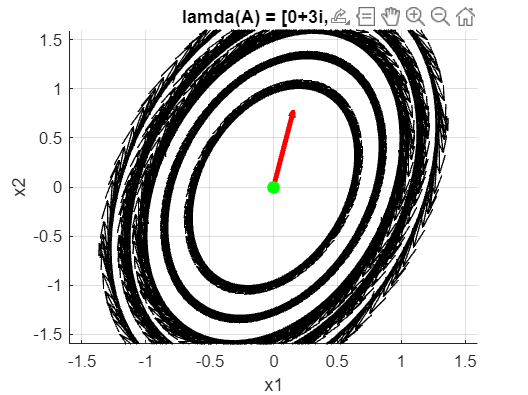

axis([-1.6 1.6 -1.6 1.6]);

A = A4k;
draw_phase()

w =    0.7071 + 0.0000i   0.7071 + 0.0000i
   0.0000 + 0.7071i   0.0000 - 0.7071i


J =    0.0000 + 3.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 - 3.0000i


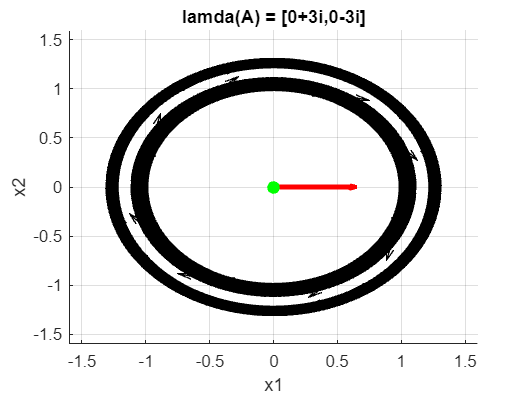

axis([-1.6 1.6 -1.6 1.6]);

Węzeł zdegenerowany stabilny, e1 = e2 = -2

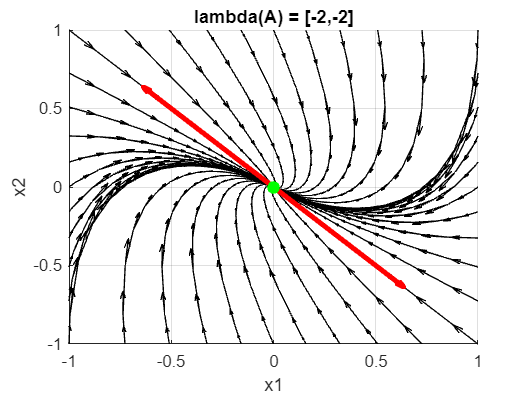

A5 = [-1 1; -1 -3];  % Węzeł stabilny
A5k = [-2 1; 0 -2];

A = A5;
draw_phase()
axis([-1 1 -1 1]);

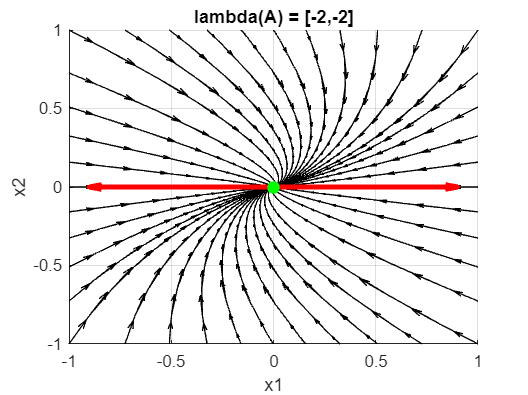

A = A5k;
draw_phase()
axis([-1 1 -1 1]);

zdeg Niestabilny

poles = [2, 2];  % Zadane wartości własne
[num, den] = tfdata(zpk(0, poles, 1, 1));
eA = tf2ss(num{1}, den{1})

eA =      4    -4
     1     0


eigvals = eig(eA)   % Sprawdzenie

eigvals =      2
     2



A5n = eA;
A5nk = jordan(eA)  % Postać kanoniczna

A5nk =      2     1
     0     2


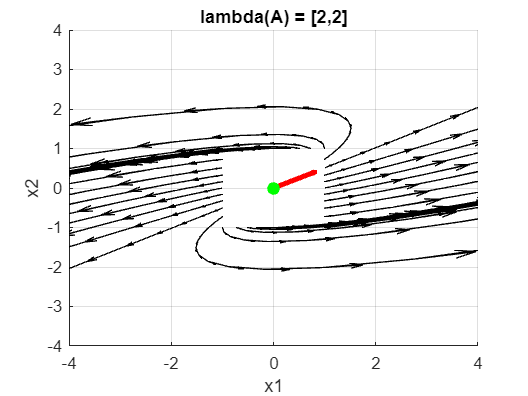


A = A5n;
draw_phase()
axis([-4 4 -4 4]);

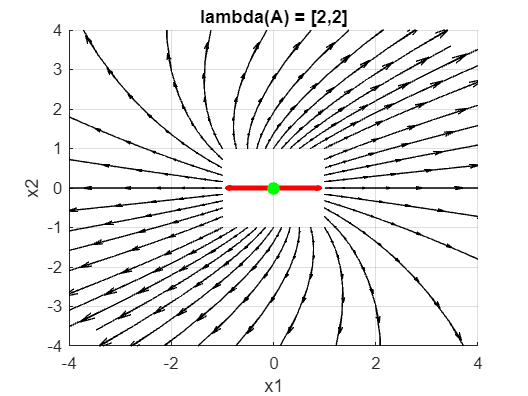

A = A5nk;
draw_phase()
axis([-4 4 -4 4]);

Gwiazda stabilna, e1 = e2 = -2

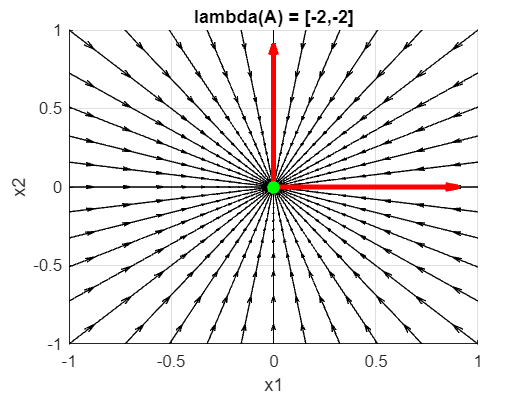

A6k = [-2 0; 0 -2];  % Gwiazda stabilna

A = A6k;
draw_phase()

gwiazda niestabilna

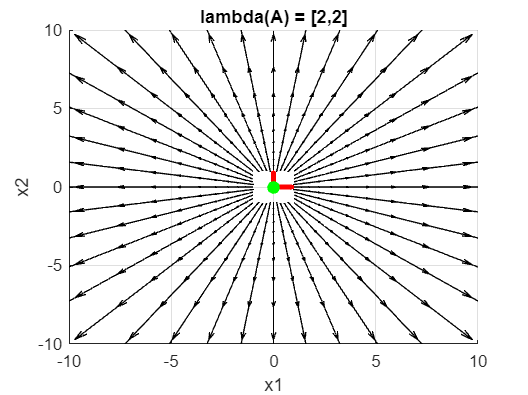

A6nk = [2 0; 0 2];  % Gwiazda niestabilna

A = A6nk;
draw_phase()
axis([-10 10 -10 10]);

Jedna wartość własna zerowa, e1 = -5, e2 = 0

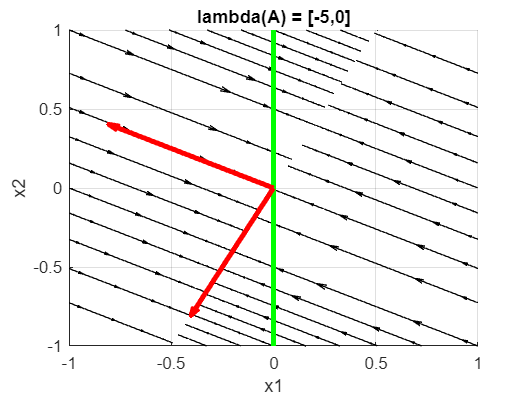

A7 = [-4 2; 2 -1];
A7k = [-5 0; 0 0];

A = A7;
draw_phase()
axis([-1 1 -1 1]);

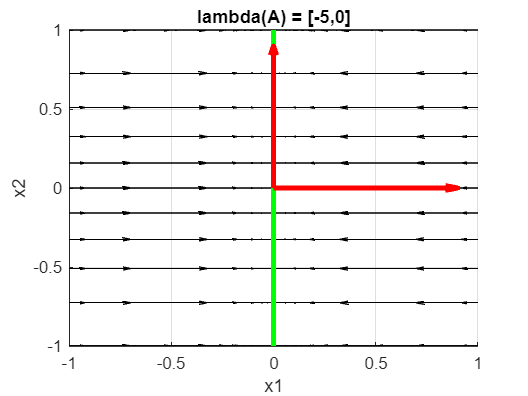

A = A7k;
draw_phase();
axis([-1 1 -1 1]);

poles = [0, 0];  % Zadane wartości własne
[num, den] = tfdata(zpk(0, poles, 8, 1));
eA = tf2ss(num{1}, den{1})

eA =      0     0
     1     0



eigvals = eig(eA)   % Sprawdzenie

eigvals =      0
     0



A8 = eA;
A8k = jordan(eA)  % Postać kanoniczna

A8k =      0     1
     0     0


e1 = e2 = 0

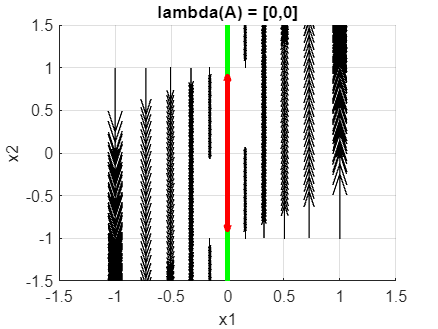

A = A8;
draw_phase()
axis([-1.5 1.5 -1.5 1.5]);

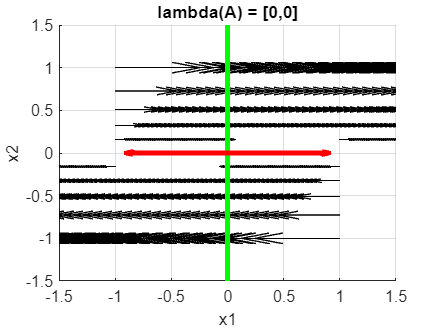

A = A8k;
draw_phase()
axis([-1.5 1.5 -1.5 1.5]);

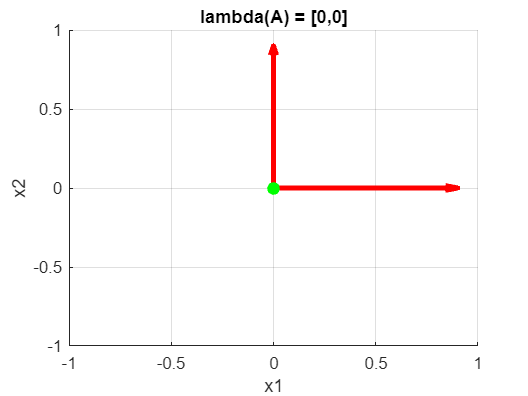

A9 = [0 0; 0 0];
A = A9;
draw_phase()

[A, Ak] = example_matrix([1, 0.5])

A =     1.5000   -0.5000
    1.0000         0


Ak =     0.5000         0
         0    1.0000


function [] = draw_phase()
    global A x0
    T=6;
    [w, J] = eig(A);
    figure; hold on; grid on;
    a = 0 : pi/20 : 2*pi; X1 = [cos(a); sin(a)];
    X2 = X1 ./ [max(abs(X1)); max(abs(X1))];
    M = size(X2, 2);
    
    for i = 1:M
        x0 = X2(:, i);
        puste = sim('model.slx', T);
        x = puste.x.signals.values;
        % Strzałki na portrecie fazowym
        quiver(x(:,1), x(:,2), gradient(x(:, 1)), gradient(x(:, 2)), "k");
        % Portret fazowy
        plot(x(:, 1), x(:,2), 'k-');
        % Zbiory równowagi - policzone według równania Ax = [0; 0]
        y_bal = linspace(-10, 10, 100);
        %plot(x_bal, 0.*x_bal, "g-", "LineWidth", 3);
        plot(0 .* y_bal, y_bal, "g-", "LineWidth", 3);
        % Wektory własne - strzałki
        quiver(0, 0, w(1, 1), w(2,1), 'r', "LineWidth", 3);
        quiver(0, 0, w(1, 2), w(2,2), 'r', "LineWidth", 3);
        % Zbiory równowagi - policzone według równania Ax = [0; 0]
        %plot(0, 0, "go", "MarkerSize", 7, "MarkerFaceColor", "g");
        title(['lambda(A) = [', num2str(J(1,1)), ',', num2str(J(2,2)), ']']);
        xlabel('x1'); ylabel('x2');
    end

    hold off;
end

function [A, Ak] = example_matrix(poles)
    [num, den] = tfdata(zpk(0, poles, 1, 1));
    A = tf2ss(num{1}, den{1});
    
    Ak = jordan(A);  % Postac kanoniczna
end